# Meta 3

## 16. Carrega a estrutura de dados guardada na última meta (Meta 2)

load('AED1.mat', 'tabela');
disp(tabela);

                        Diretorio_Audio                         Nome_Arquivo      Digito    Participante    Repeticao    Sinal_Processado    Taxa_Amostragem    EnergiaTotal    EnergiaPrimeiraMetade    EnergiaSegundaMetade    DesvioPadraoAmplitude      RMS      MediaAmplitude    FatorCrest    TaxaCruzamento    CoeficientesFourier    AmpEspectralMaxima    FreqAmpMaxima    CentroideEspectral    FreqBordaEspectral    LarguraBandaEspectral
    _______________________________________________________    _______________    ______    ____________    _________  

## 17. Seleção das melhores características extraídas

%    Definimos um conjunto de 6 features (3 no tempo, 3 na frequência)
features = {'EnergiaTotal','FatorCrest','TaxaCruzamento', ...
            'CentroideEspectral','FreqBordaEspectral','LarguraBandaEspectral'};
%    Prepara matriz X (nAmostras × nFeatures) e vetor y de rótulos
nAmostras = height(tabela);
X = zeros(nAmostras, numel(features));
for i = 1:numel(features)
    X(:, i) = tabela.(features{i});  % Extrai coluna de cada feature
end
y = tabela.Digito;  % Rótulos reais dos dígitos

%% Classificador de Distância Mínima com Hold-Out Estratificado (70/30 por dígito)
%   Garantimos mesmo número relativo de amostras de cada digito
rng('default'); 
idxTrain = false(nAmostras,1);
idxTest  = false(nAmostras,1);
digitos_all = unique(y);
for k = 1:numel(digitos_all)
    classe = digitos_all(k);
    idxClasse = find(y == classe);        % índices de todas as repetições desse digito
    nClasse = numel(idxClasse);
    nTrain = round(0.7 * nClasse);        % 70% para treino
    perm = idxClasse(randperm(nClasse)); % baralha índices
    idxTrain(perm(1:nTrain)) = true;     % aponta amostras de treino
    idxTest(perm(nTrain+1:end)) = true;  % restantes para teste
end

% Separa dados em treino e teste
X_train = X(idxTrain, :);
y_train = y(idxTrain);
X_test  = X(idxTest, :);
y_test  = y(idxTest);

% Cálculo de centroides das classes no conjunto de treino
digitos = unique(y_train);
centroids = zeros(numel(digitos), size(X,2));
for k = 1:numel(digitos)
    % Média das features para cada digito
    centroids(k,:) = mean(X_train(y_train==digitos(k),:), 1);
end

% Predição: atribui a cada amostra de teste a classe do centroide mais próximo
nTest = sum(idxTest);
predicted = zeros(nTest,1);
for i = 1:nTest
    distVec = vecnorm(X_test(i,:) - centroids, 2, 2); % distâncias euclidianas
    [~, minIdx] = min(distVec);
    predicted(i) = digitos(minIdx);
end

%% Avaliação do Classificador
numAcertos = sum(predicted == y_test);
percentAcertos = (numAcertos / nTest) * 100;
fprintf('Acurácia global estratificada: %d/%d (%.2f%%)', numAcertos, nTest, percentAcertos);

Acurácia global estratificada: 74/150 (49.33%)


% Percentual de acerto estratificado por dígito
fprintf('Acurácia estratificada por dígito:');

Acurácia estratificada por dígito:

digitosTest = unique(y_test);
for k = 1:numel(digitosTest)
    classe = digitosTest(k);
    totalClasse = sum(y_test == classe);
    acertosClasse = sum(predicted(y_test == classe) == classe);
    percClasseAcc = (acertosClasse / totalClasse) * 100;
    fprintf('Dígito %d: %.2f%% (%d/%d)\n', classe, percClasseAcc, acertosClasse, totalClasse);
end

Dígito 0: 20.00% (3/15)
Dígito 1: 66.67% (10/15)
Dígito 2: 40.00% (6/15)
Dígito 3: 46.67% (7/15)
Dígito 4: 6.67% (1/15)
Dígito 5: 53.33% (8/15)
Dígito 6: 93.33% (14/15)
Dígito 7: 40.00% (6/15)
Dígito 8: 66.67% (10/15)
Dígito 9: 60.00% (9/15)


% Matriz de Confusão: identifica padrões de erro por classe
C = confusionmat(y_test, predicted);
disp('Matriz de Confusão Estratificada:');

Matriz de Confusão Estratificada:


disp(C);

     3     1     2     0     1     0     0     4     1     3
     0    10     0     0     0     0     0     0     1     4
     3     0     6     0     1     0     0     5     0     0
     0     3     0     7     2     1     0     0     0     2
     0     6     0     0     1     5     0     3     0     0
     0     1     0     0     0     8     0     4     2     0
     0     0     0     0     0     0    14     1     0     0
     0     2     1     0     0     0     5     6     1     0
     0     1     0     1     2     1     0     0    10     0
     1     3     0     0     0     0     0     0     2     9



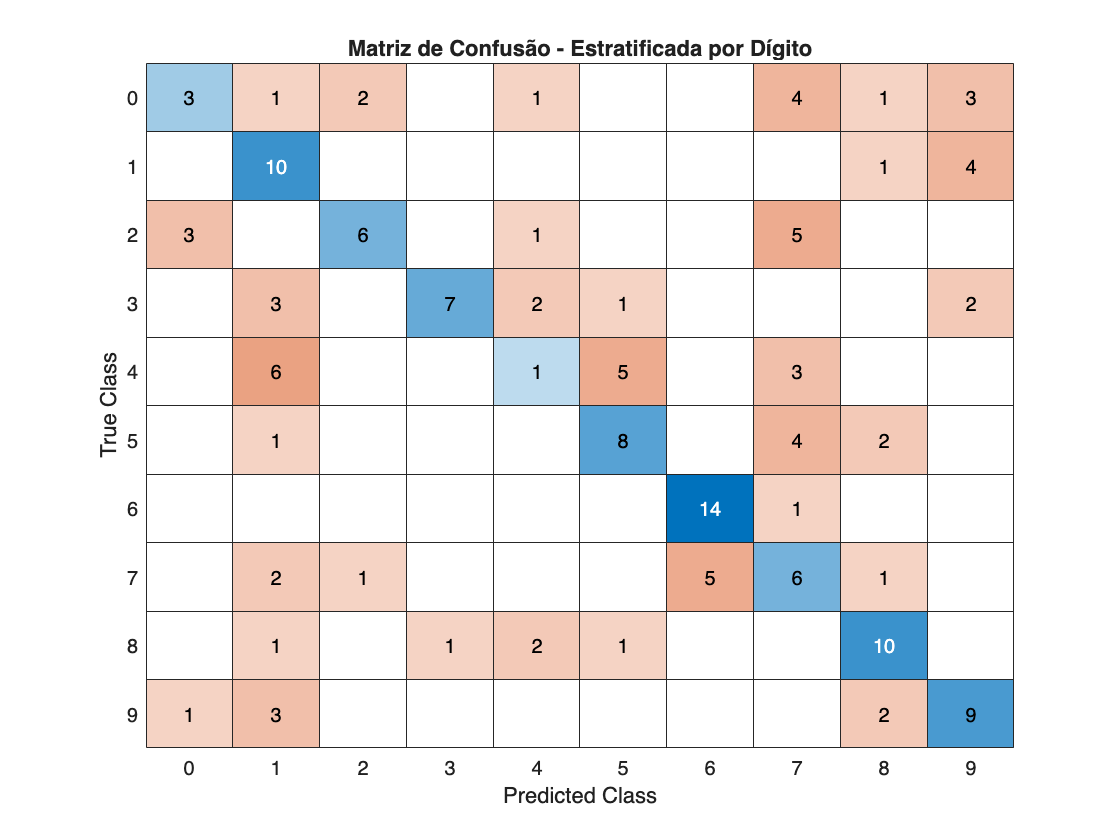

figure('Name','Matriz de Confusão Estratificada','NumberTitle','off');
confusionchart(y_test, predicted);
title('Matriz de Confusão - Estratificada por Dígito');

## Exercício 19: Formato de Janelas (comum a todos os dígitos)

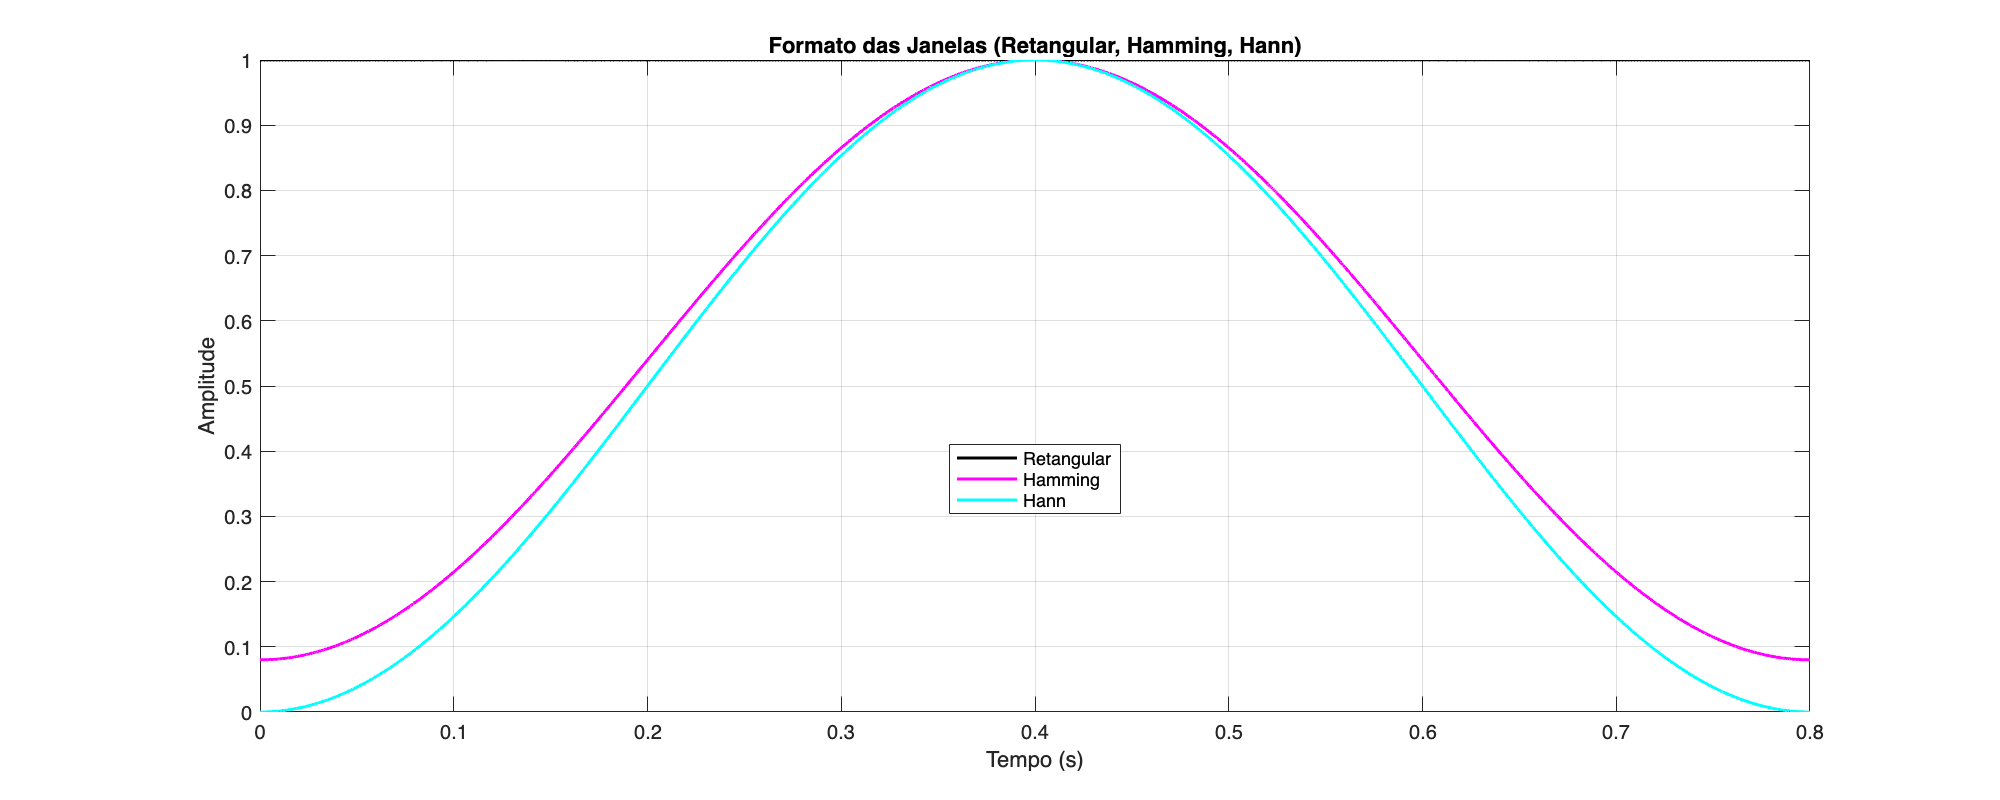

% Seleciona um sinal de exemplo (primeiro da tabela)
s0 = tabela.Sinal_Processado{1}; fs0 = tabela.Taxa_Amostragem(1);
N0 = length(s0);
t0 = (0:N0-1)/fs0;  % vetor tempo

% Define três tipos de janelas no tempo
w_rect0    = ones(N0,1);   % Retangular (nenhuma atenuação)
w_hamming0 = hamming(N0);  % Suavização moderada
w_hann0    = hann(N0);     % Suavização alternativa

% Plot do formato temporal das janelas
figure('Name','Formato das Janelas','NumberTitle','off','Position',[100 100 1000 400]);
plot(t0, w_rect0, 'k', 'LineWidth',1.5); hold on;
plot(t0, w_hamming0, 'm', 'LineWidth',1.5);
plot(t0, w_hann0, 'c', 'LineWidth',1.5);
title('Formato das Janelas (Retangular, Hamming, Hann)');
xlabel('Tempo (s)'); ylabel('Amplitude');
legend('Retangular','Hamming','Hann','Location','best'); grid on;

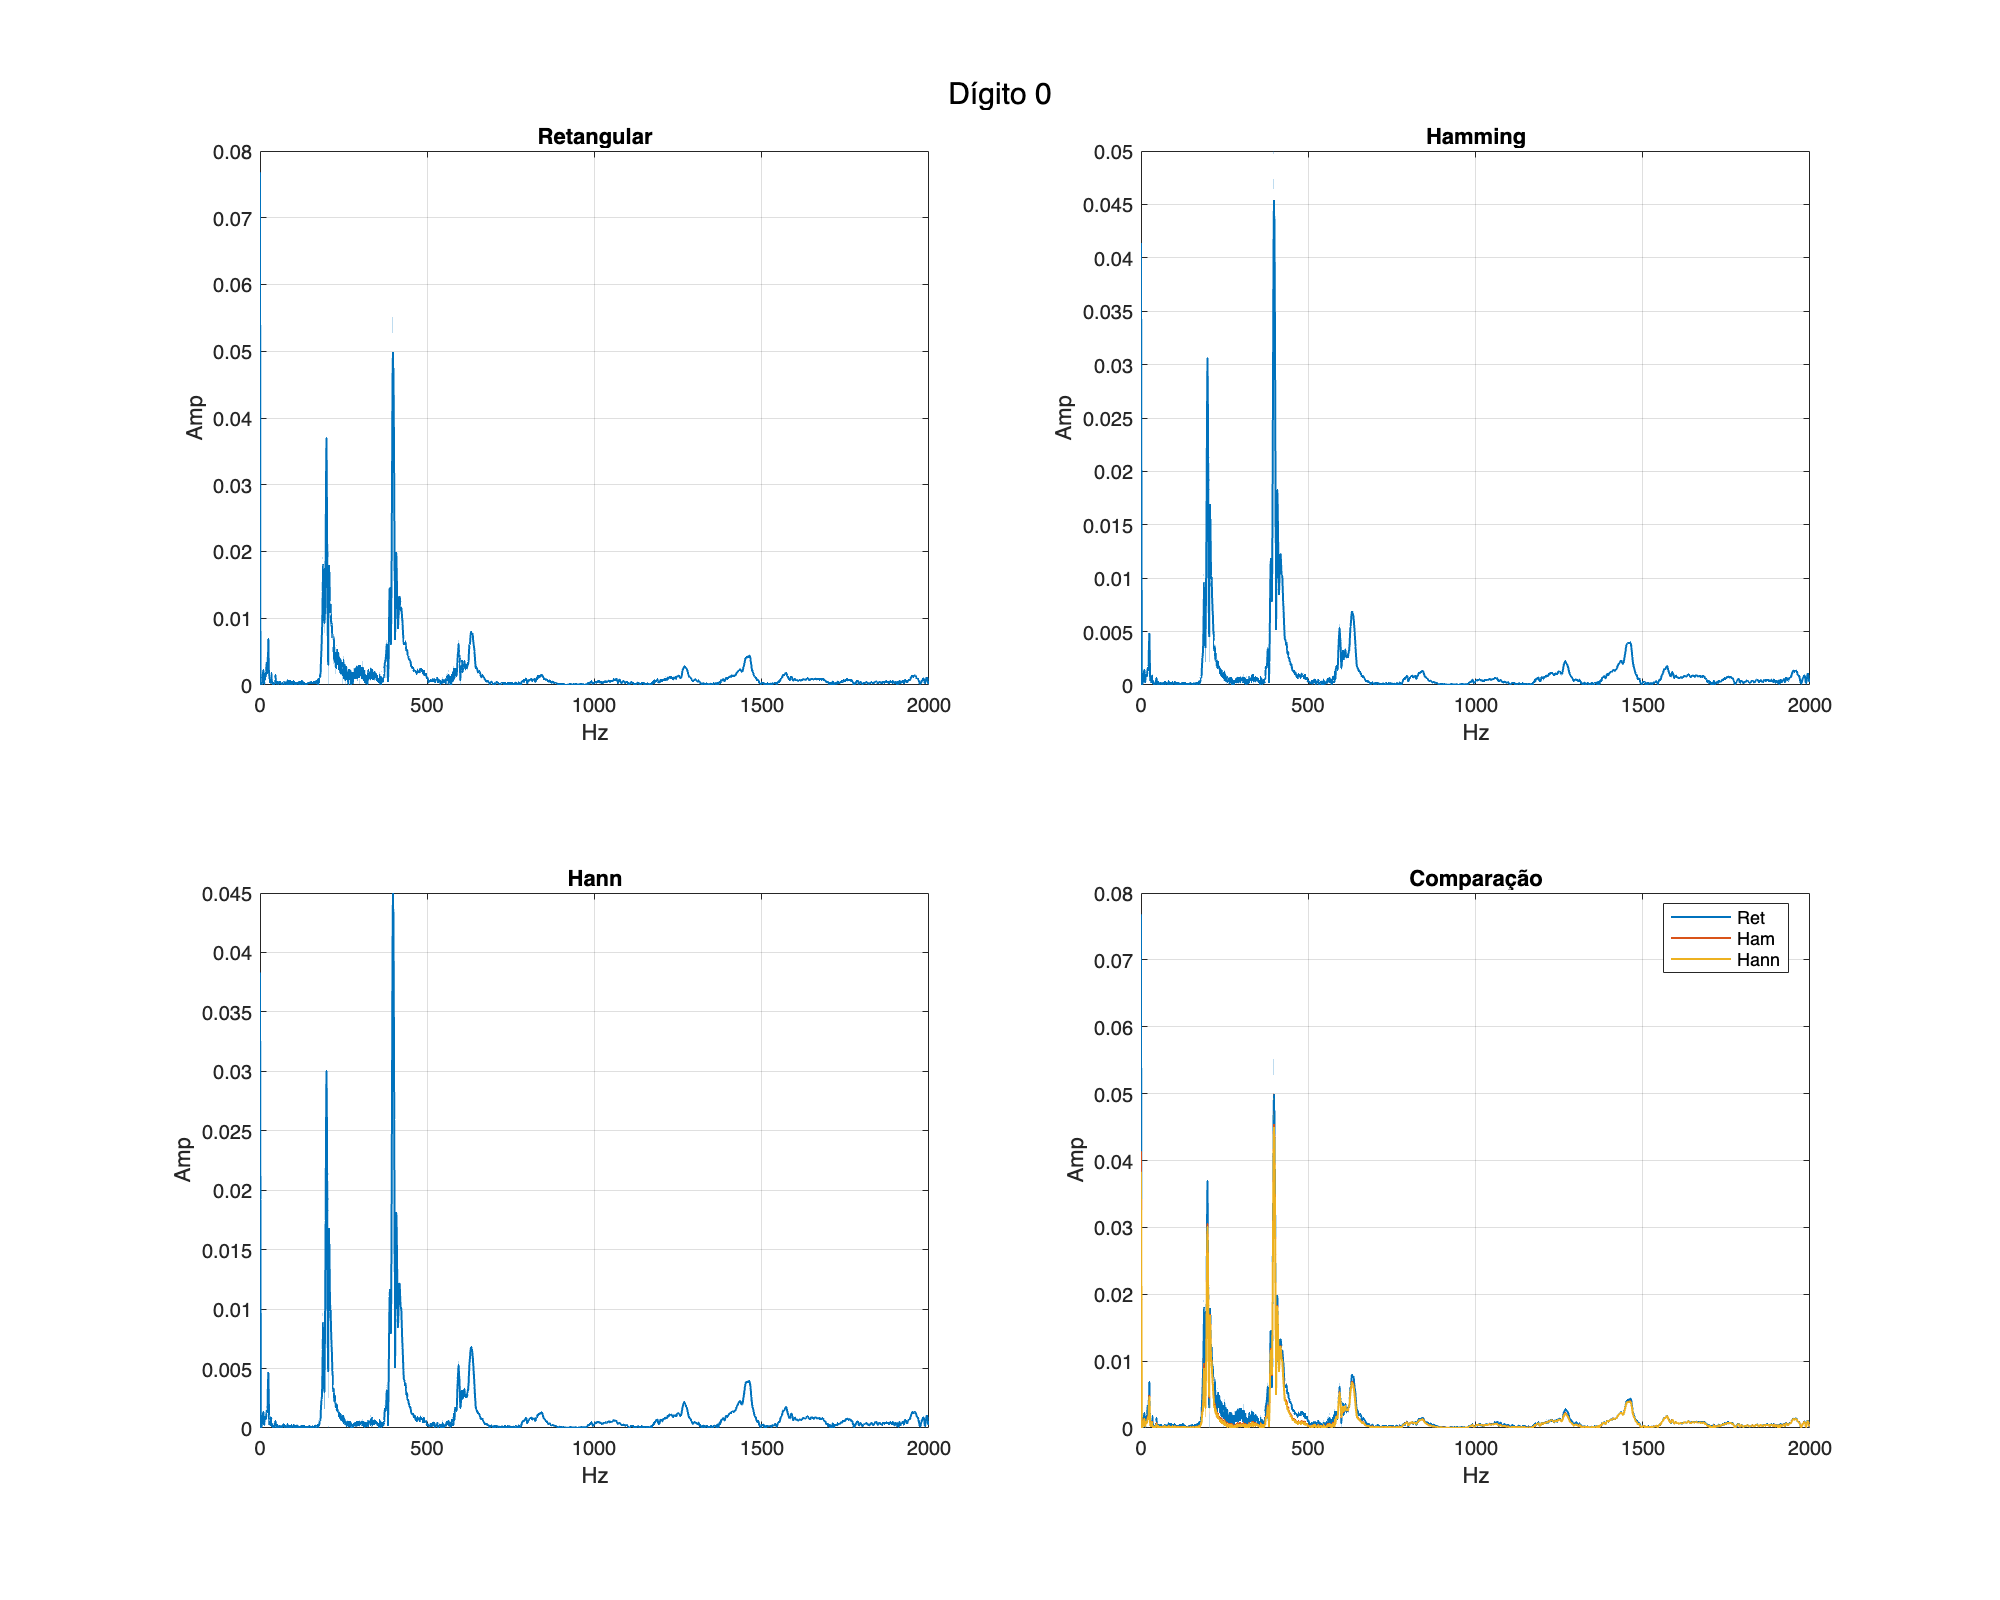

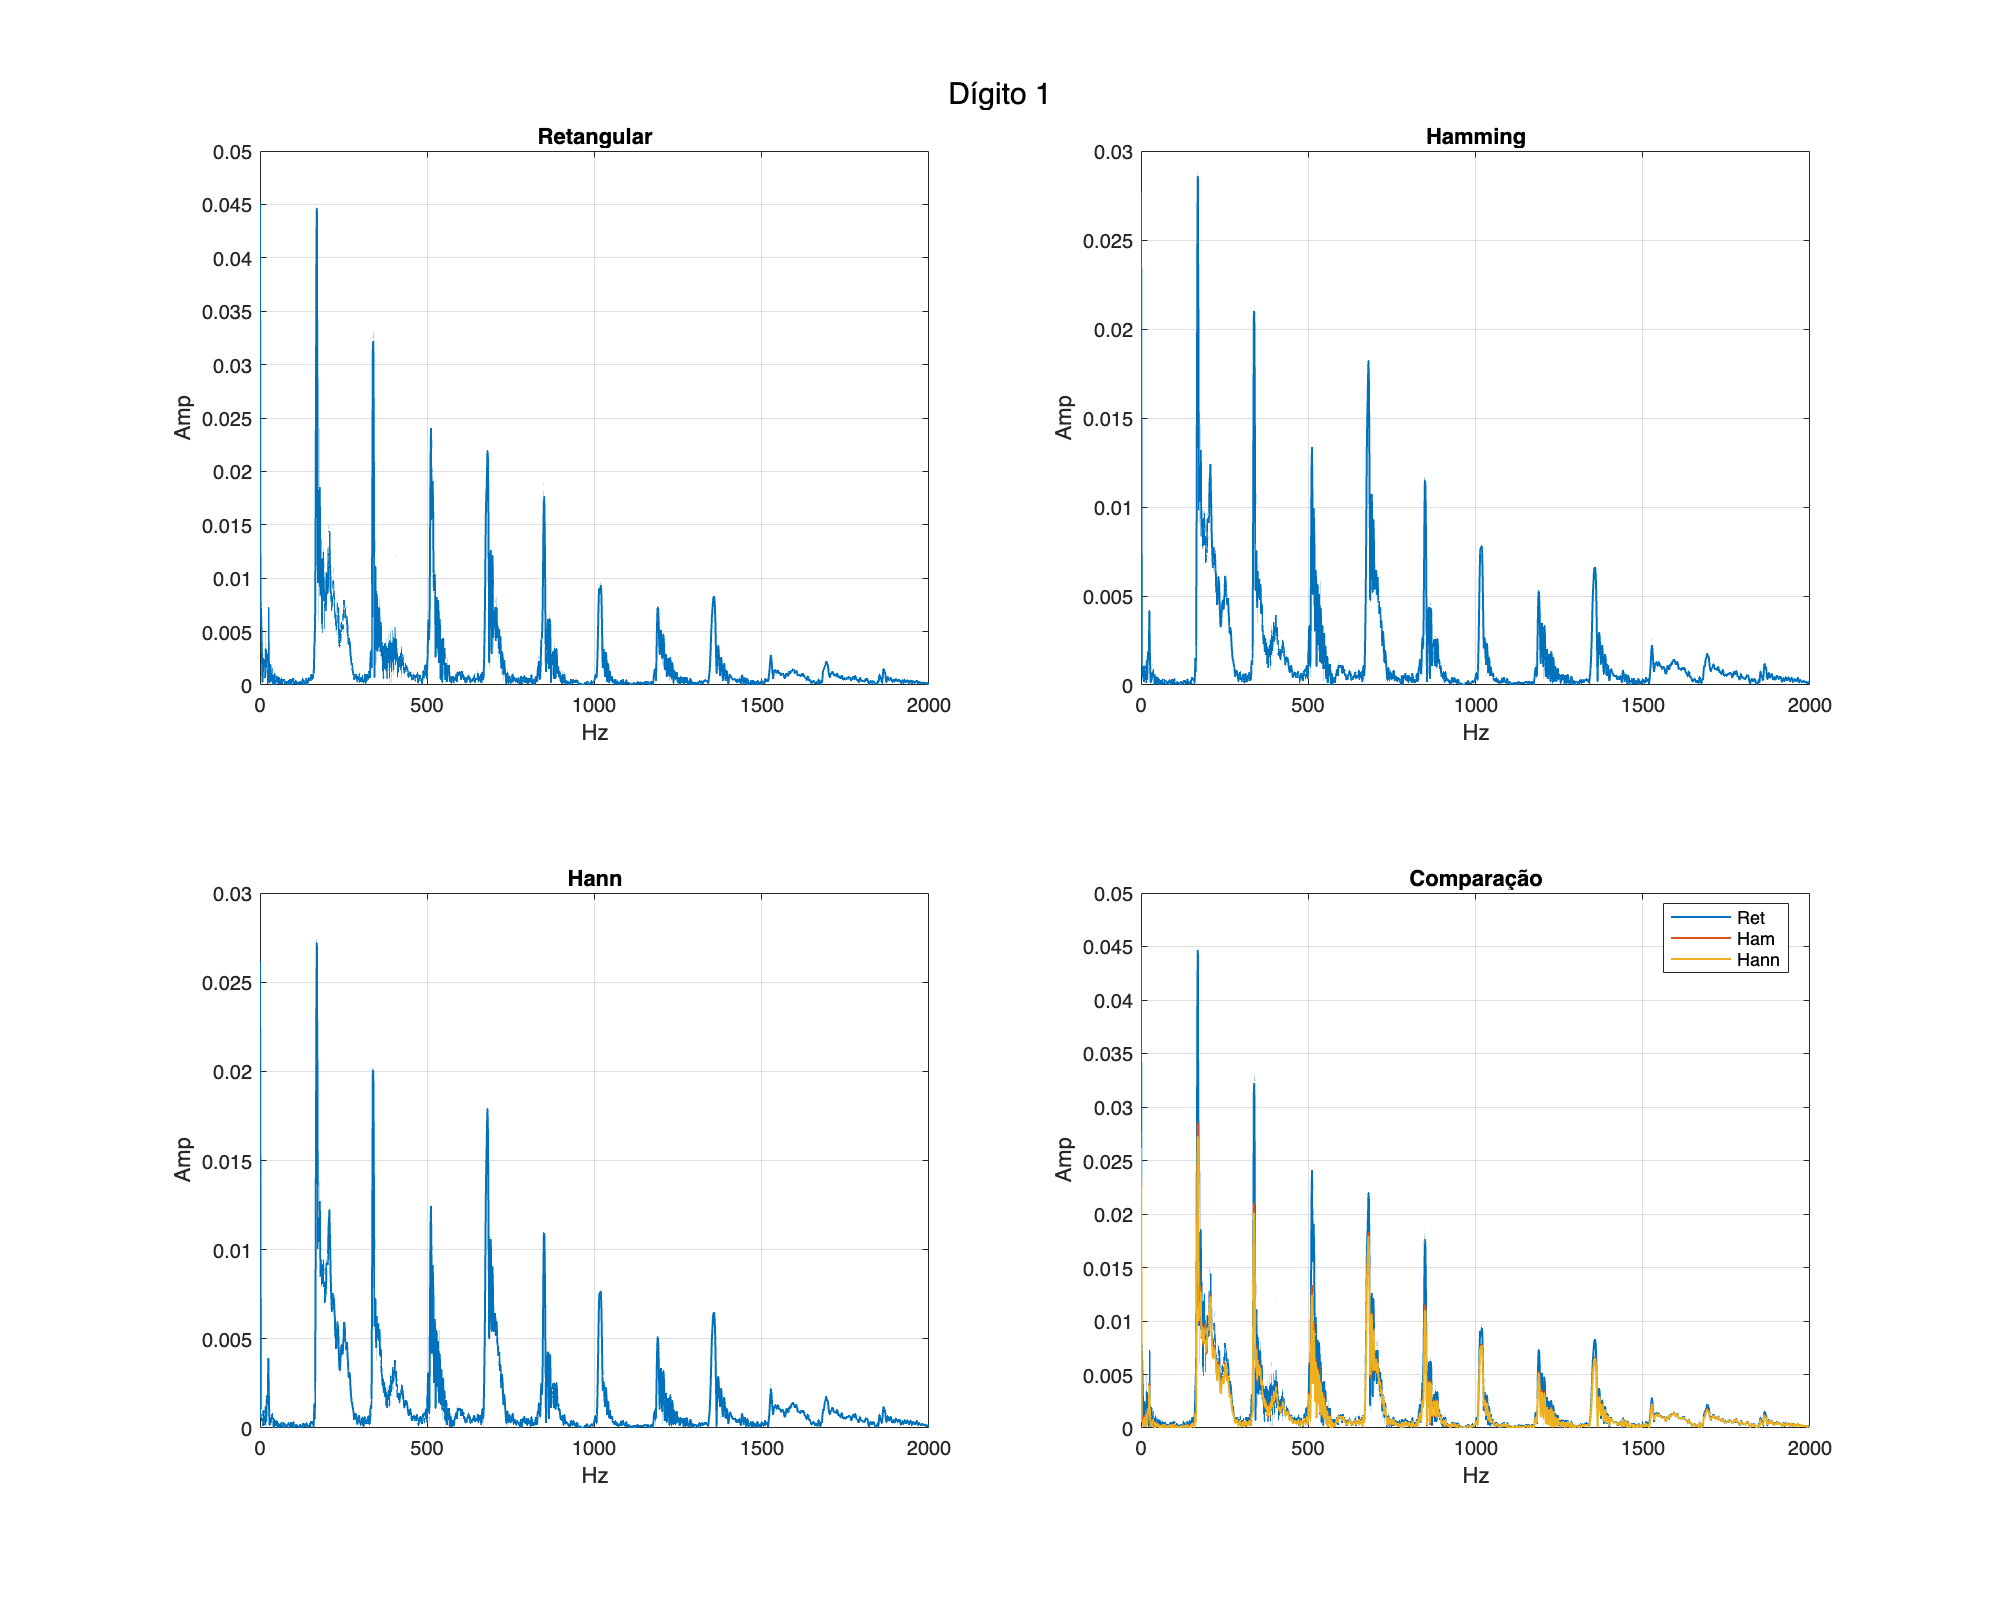

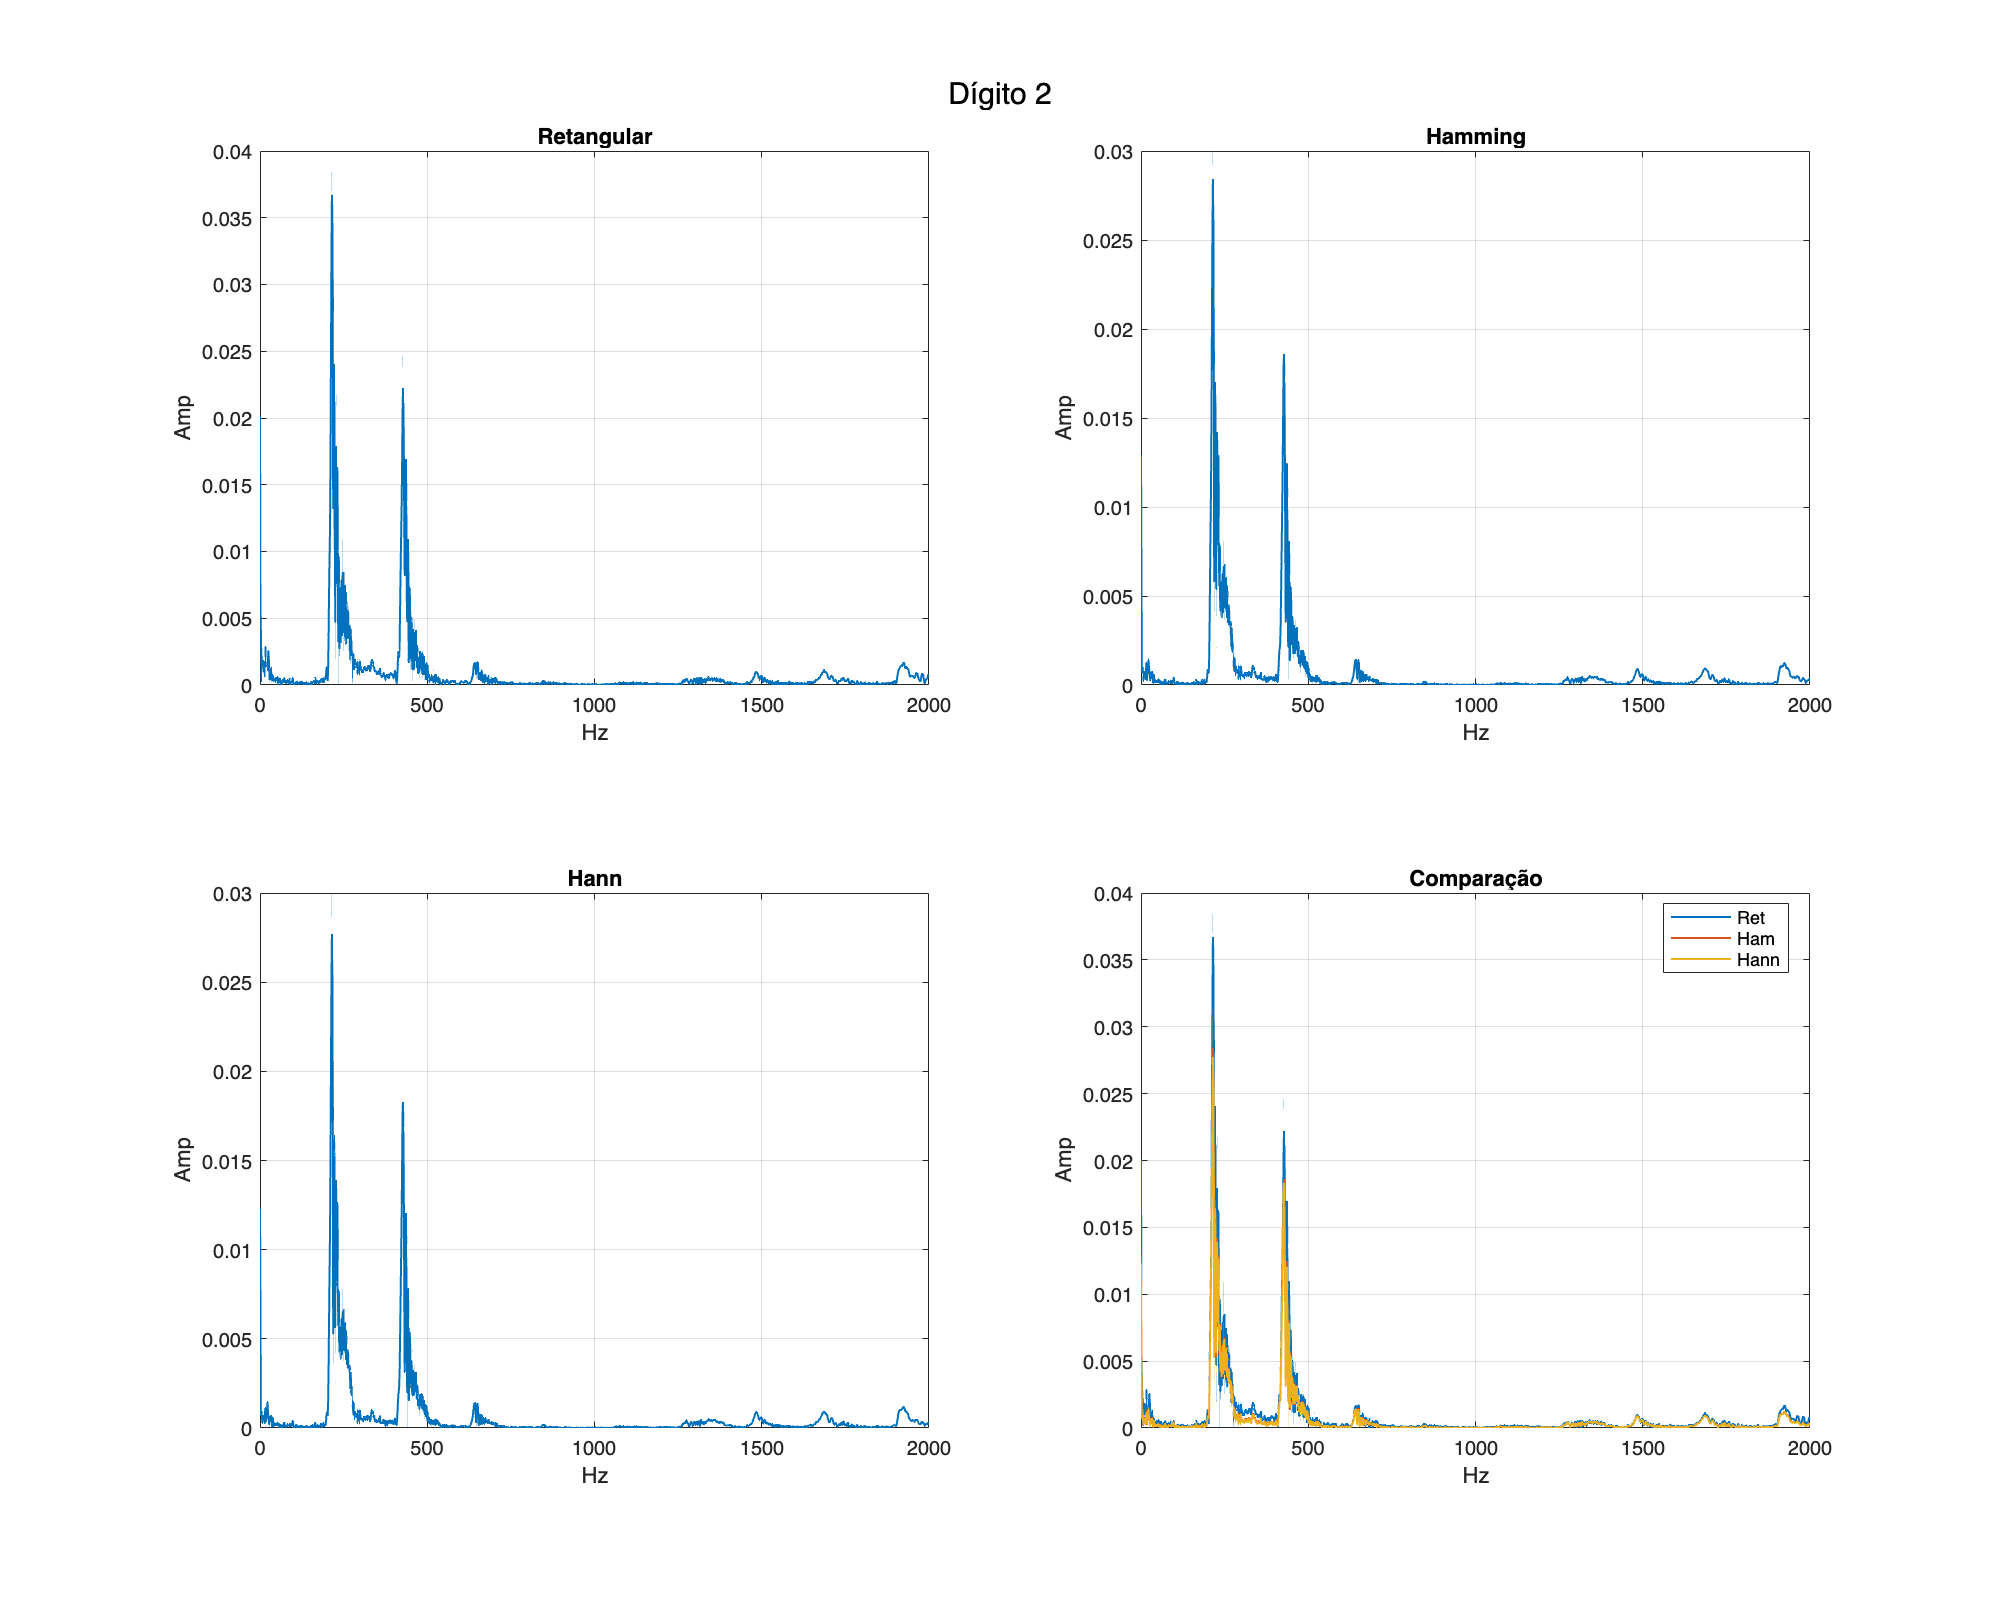

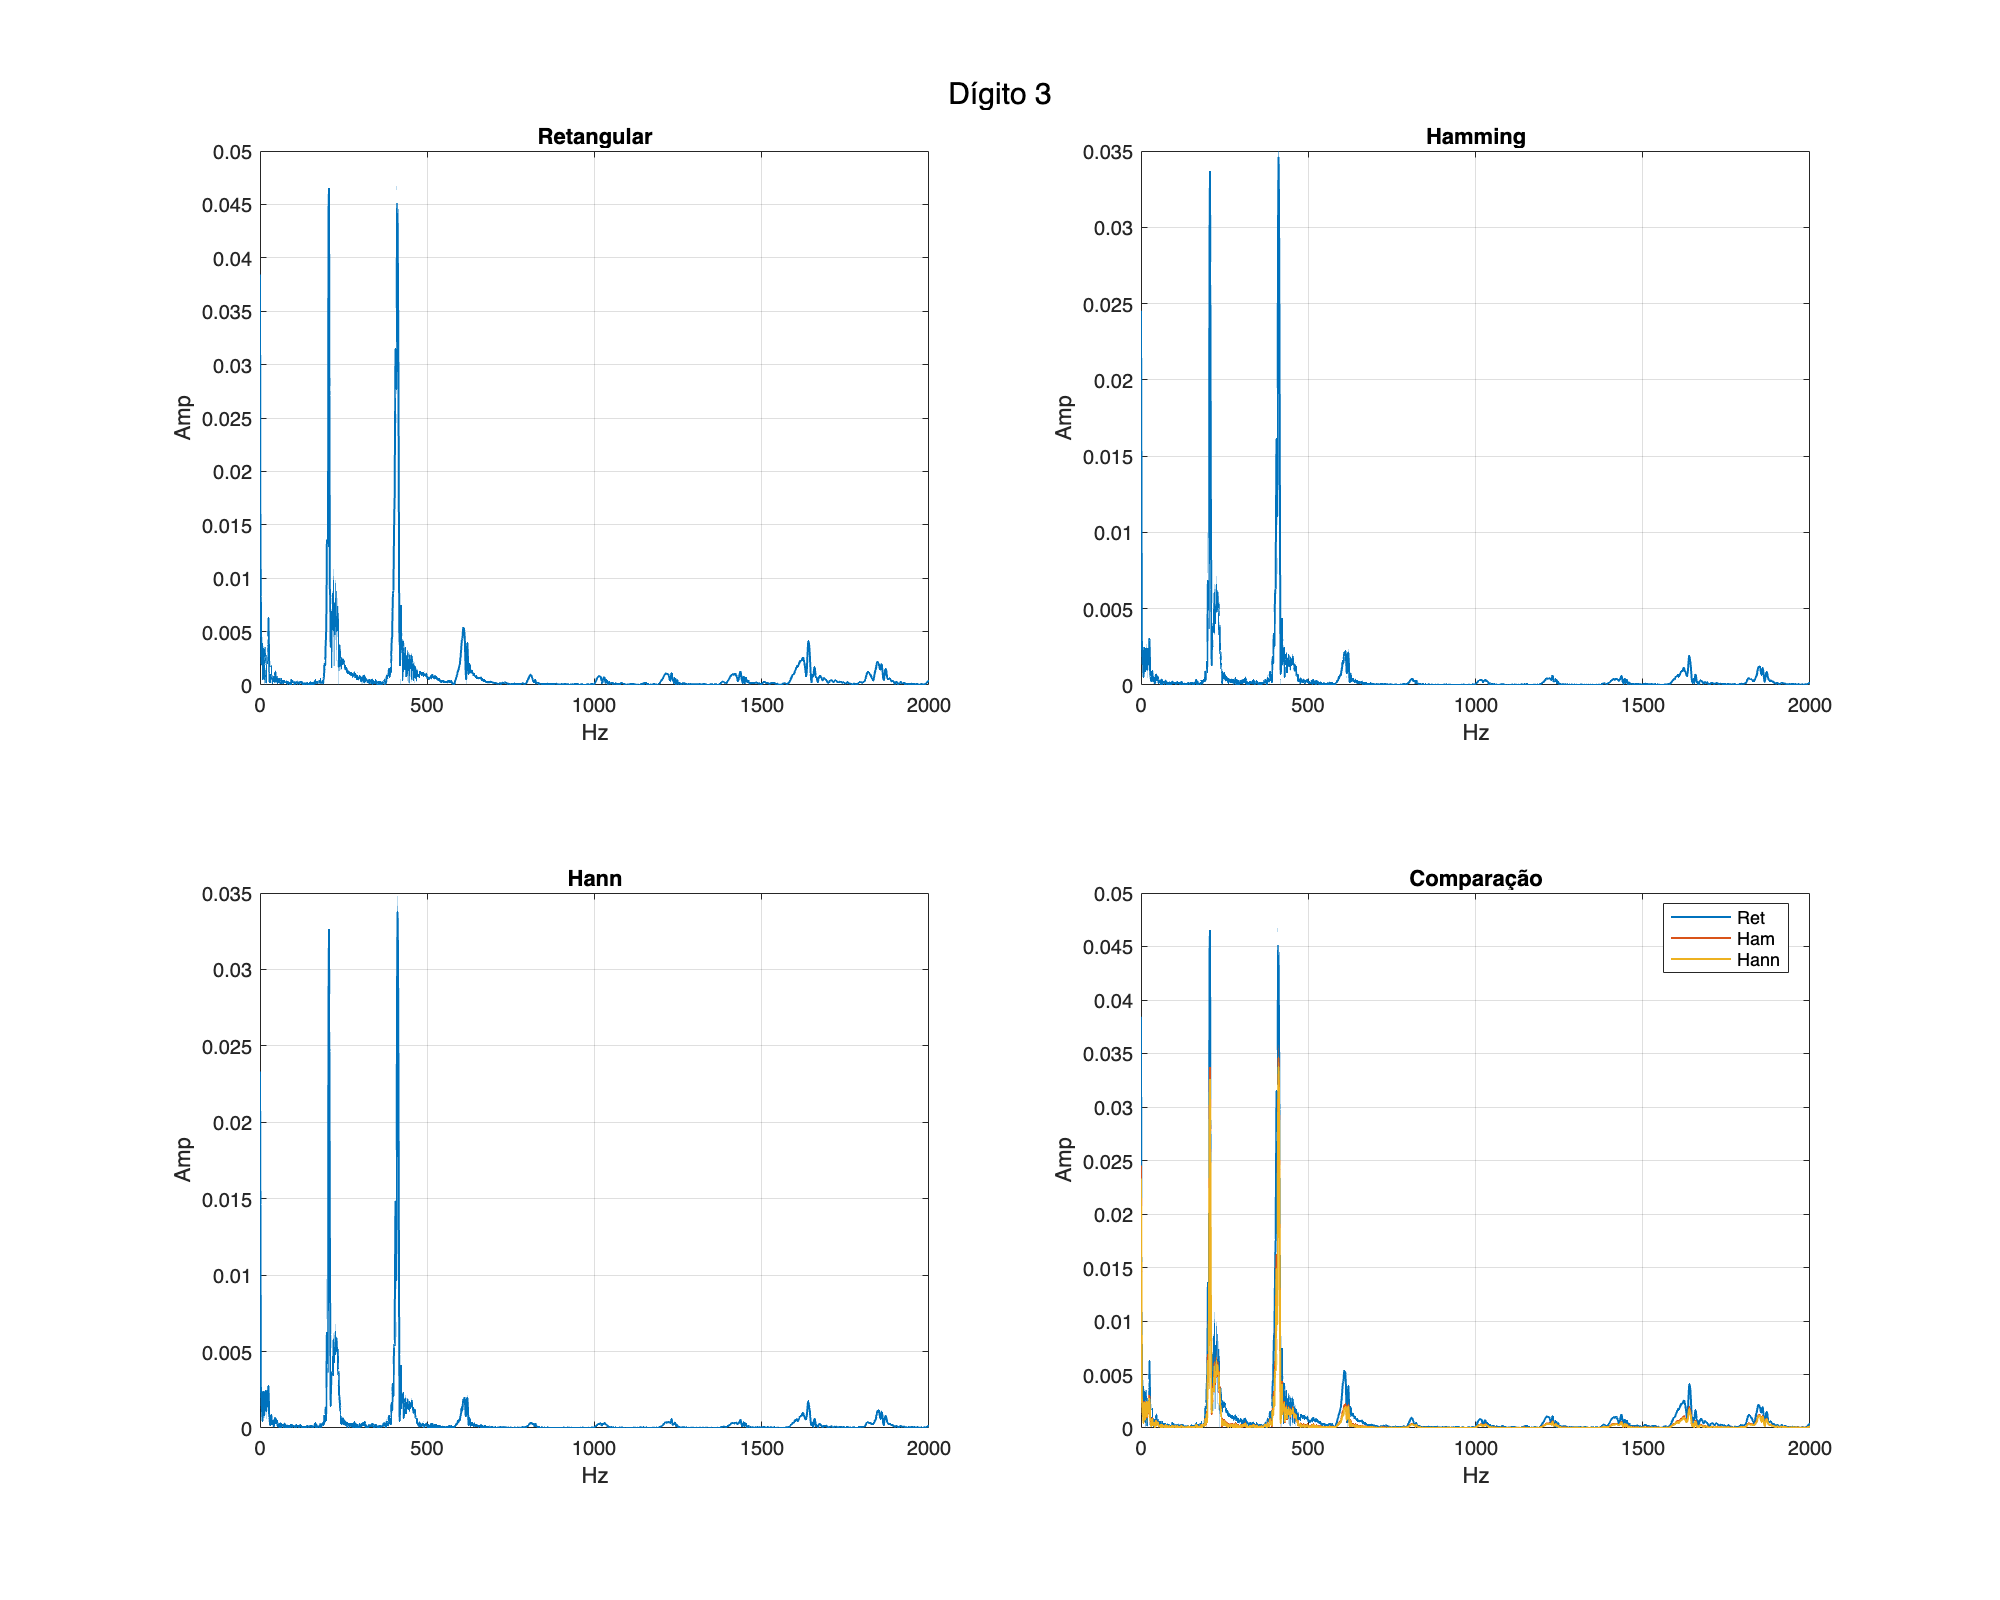

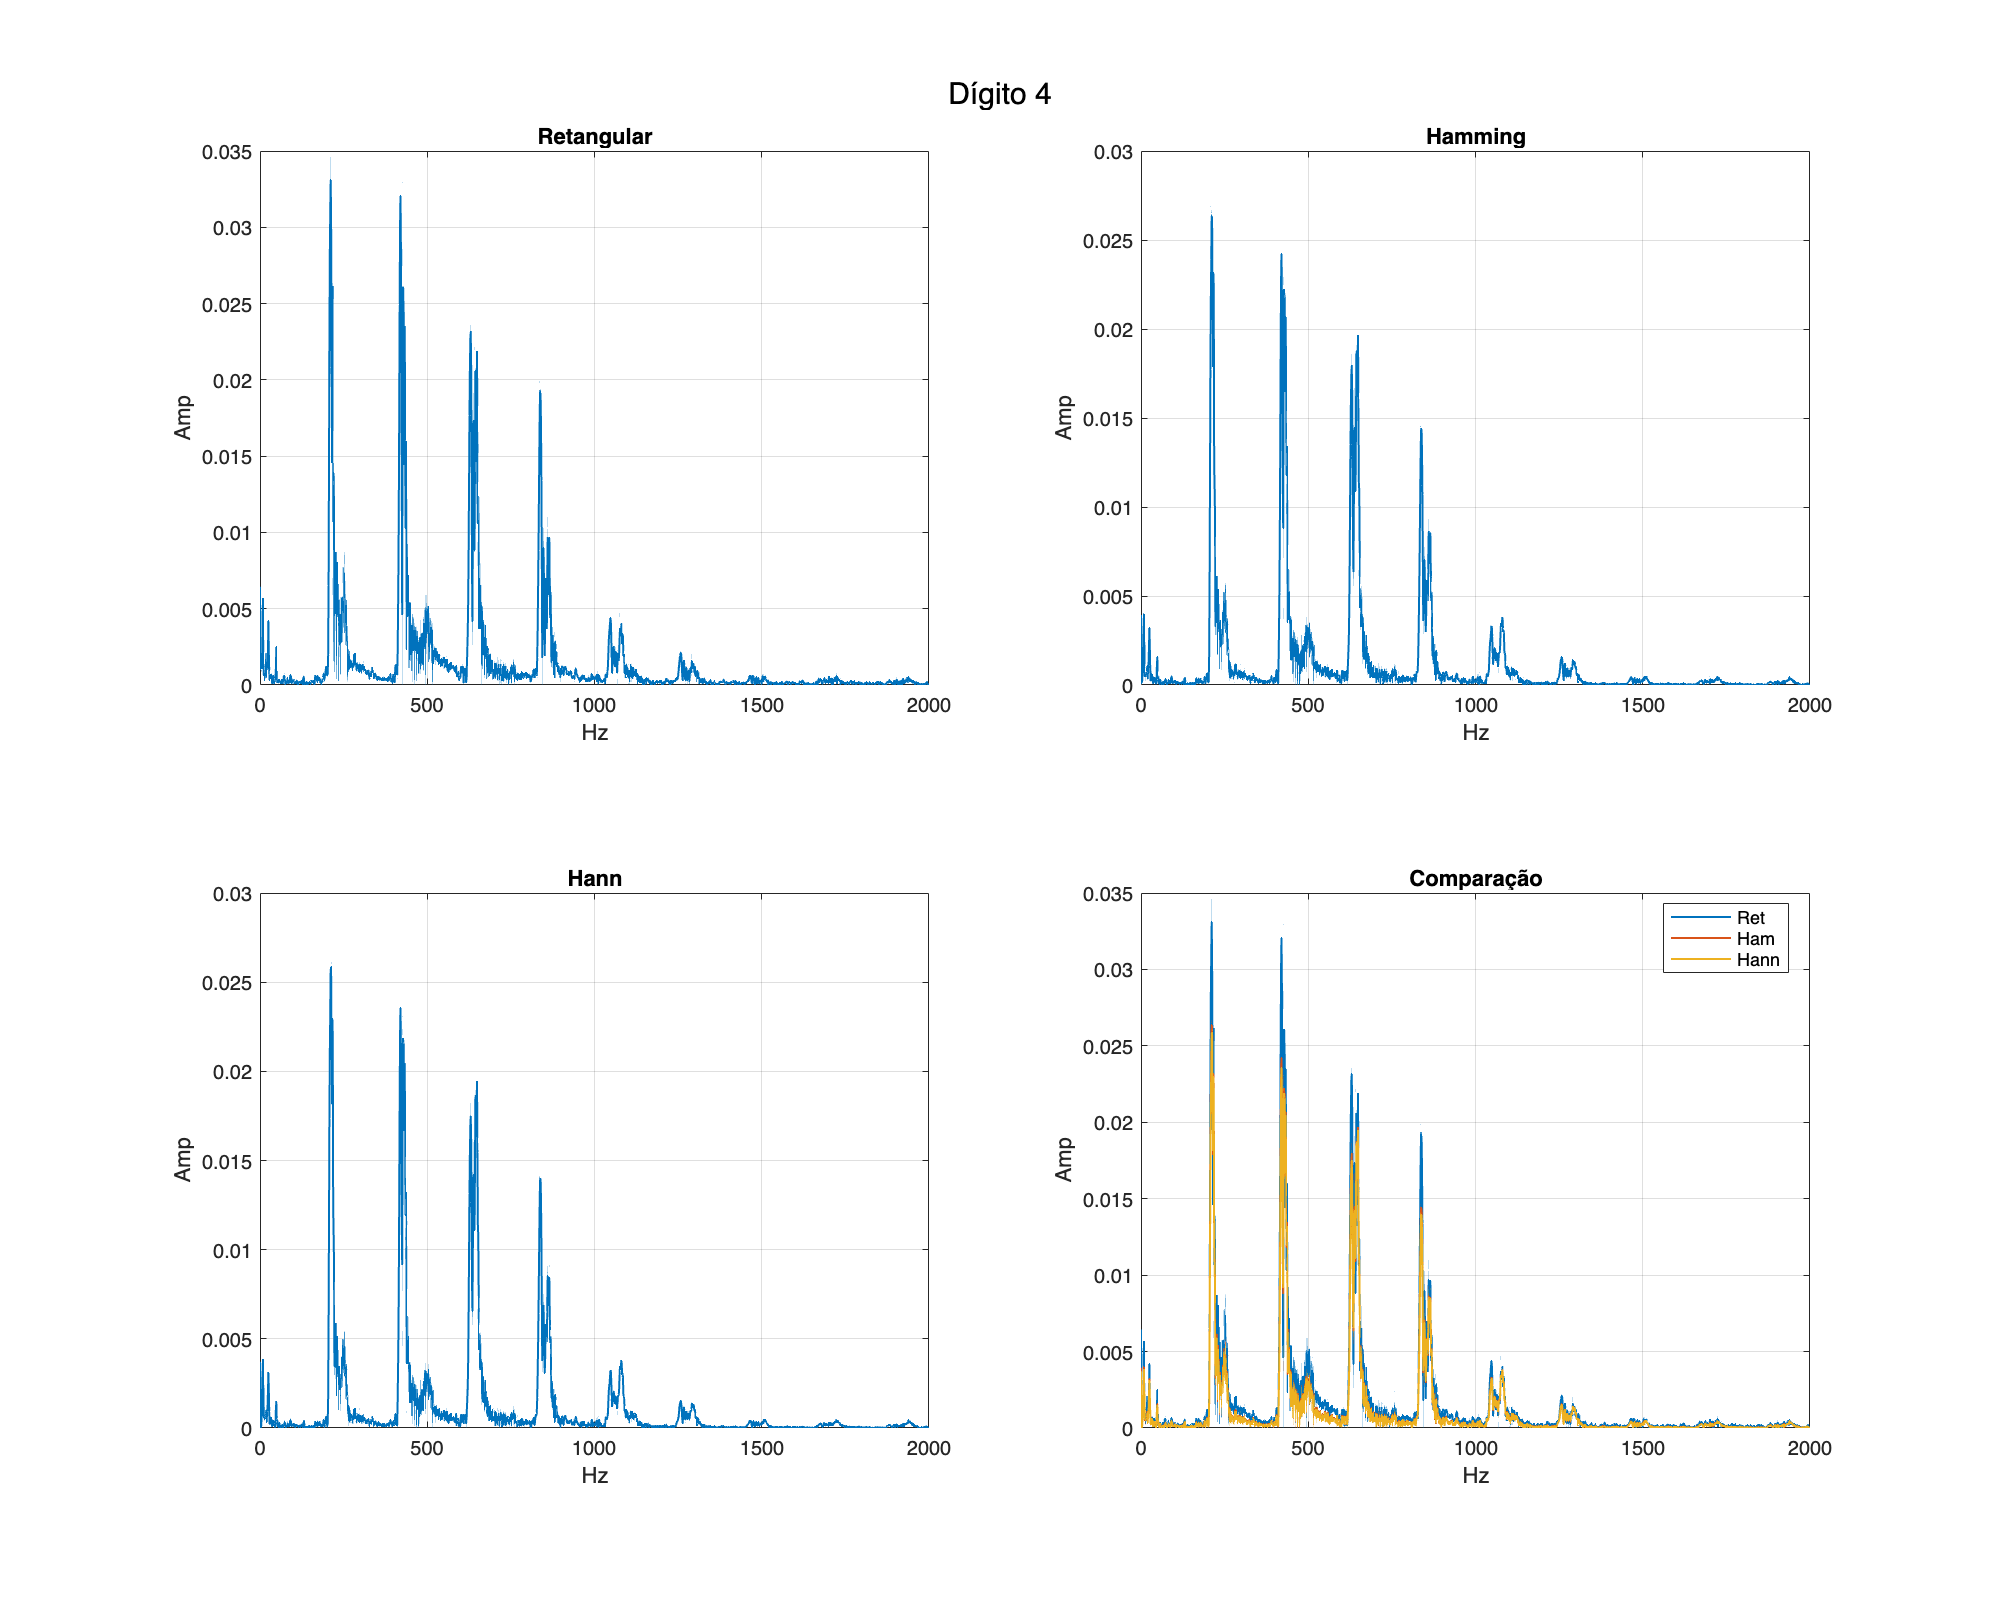

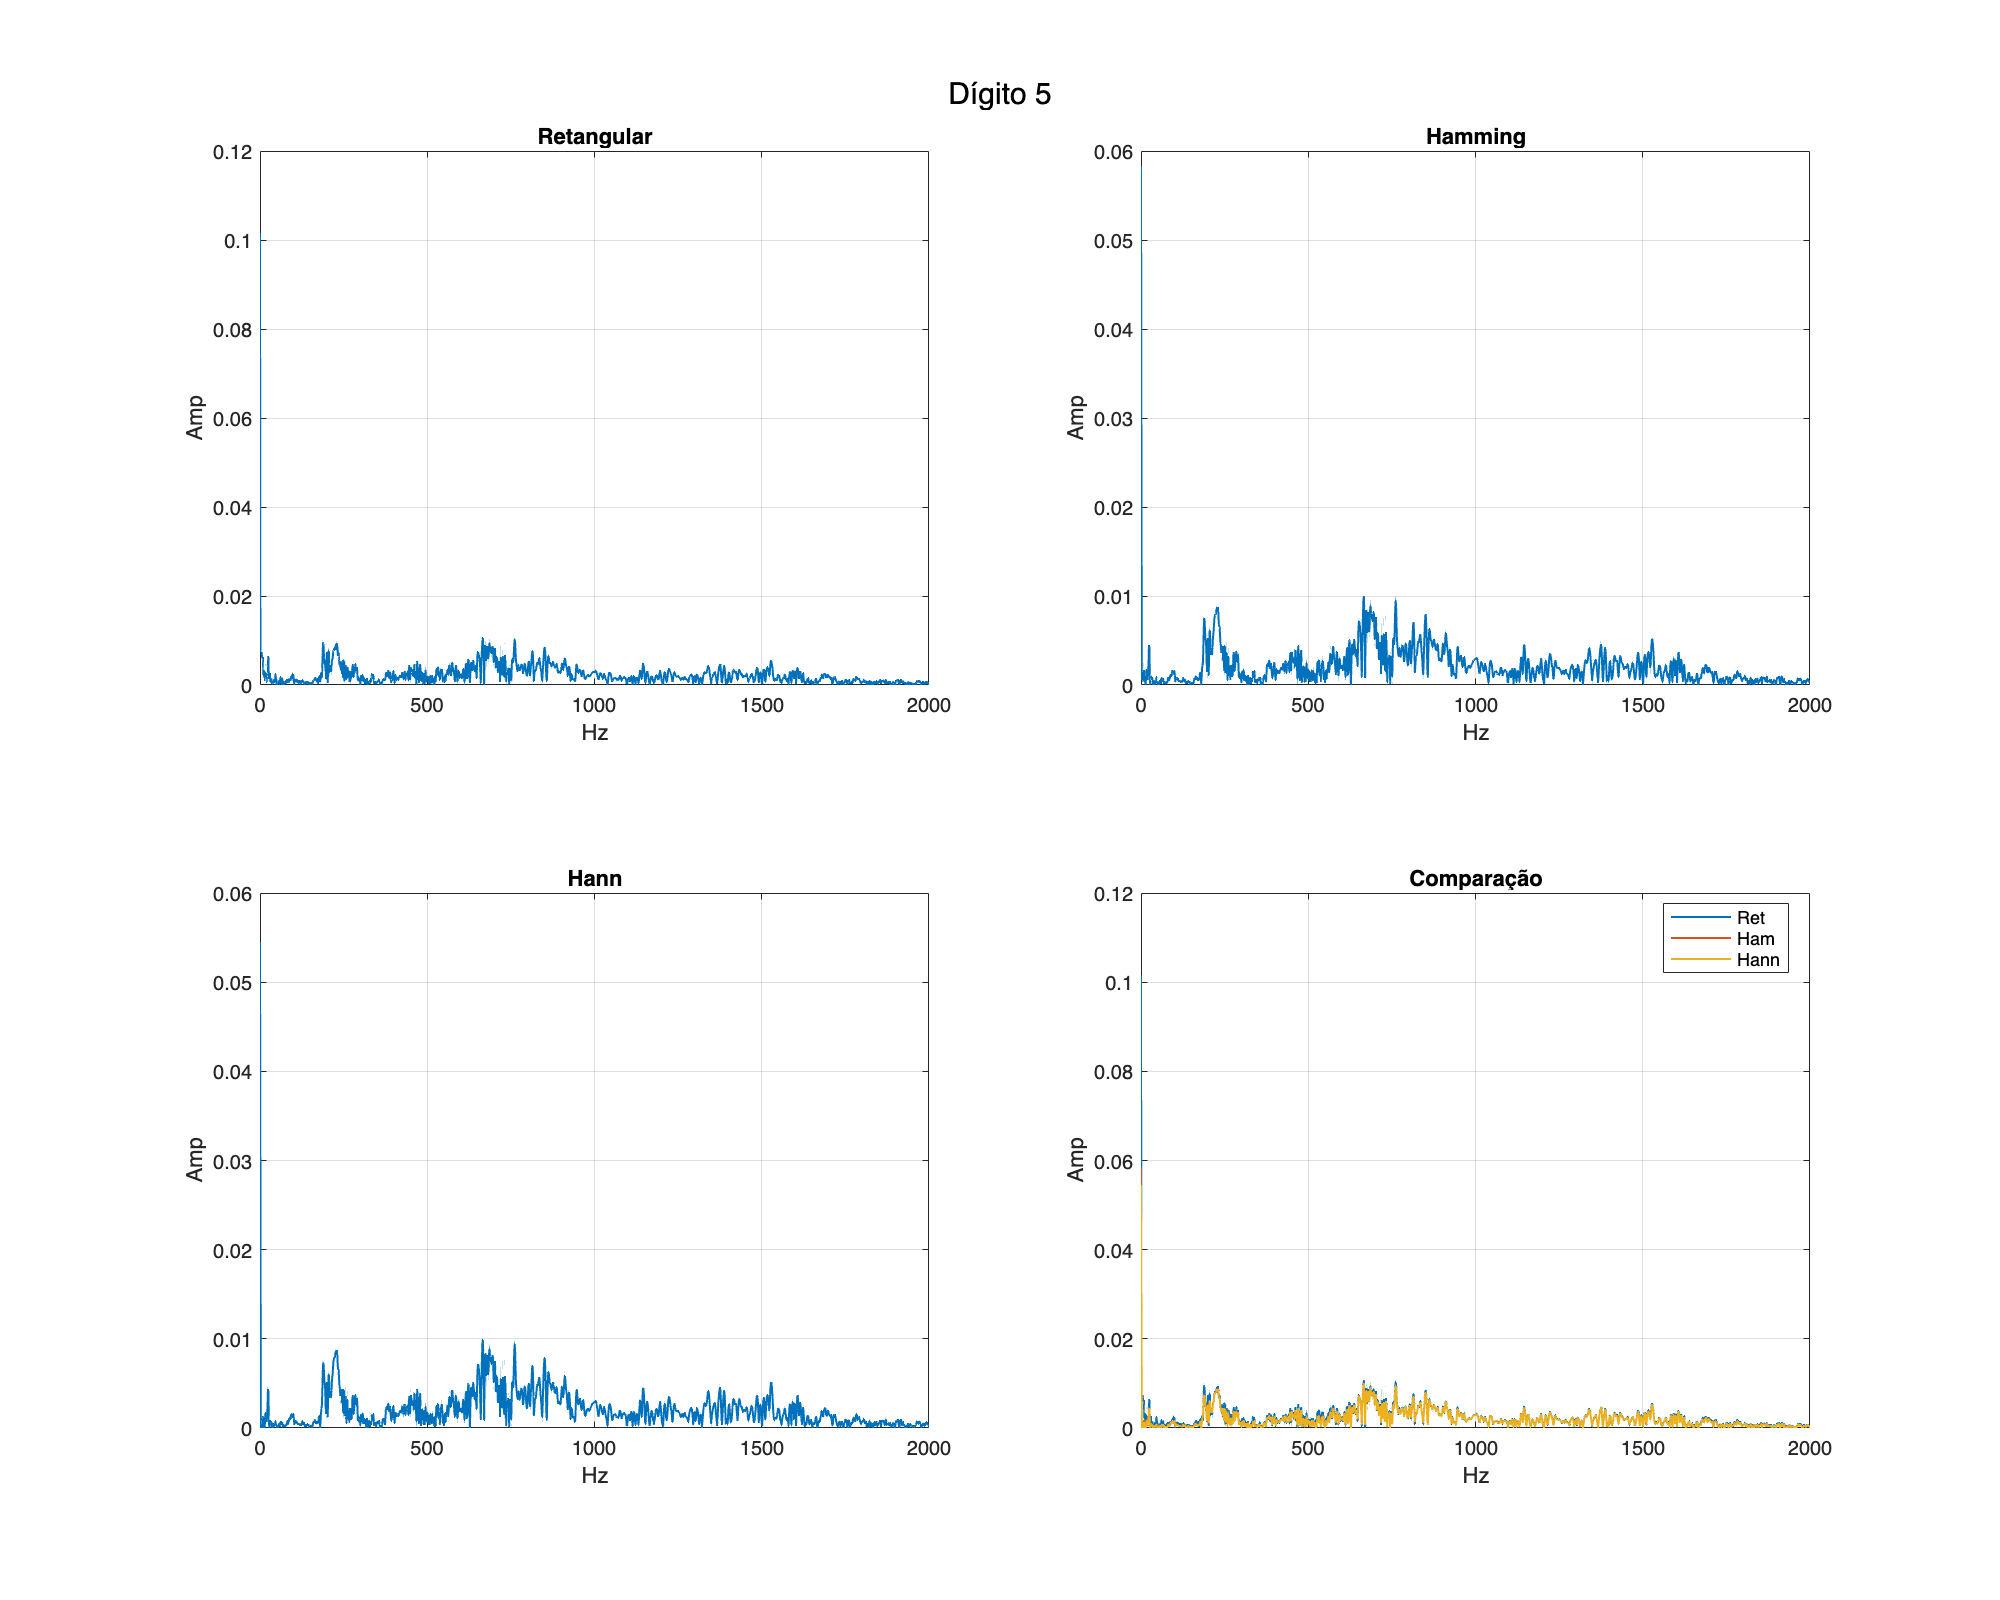

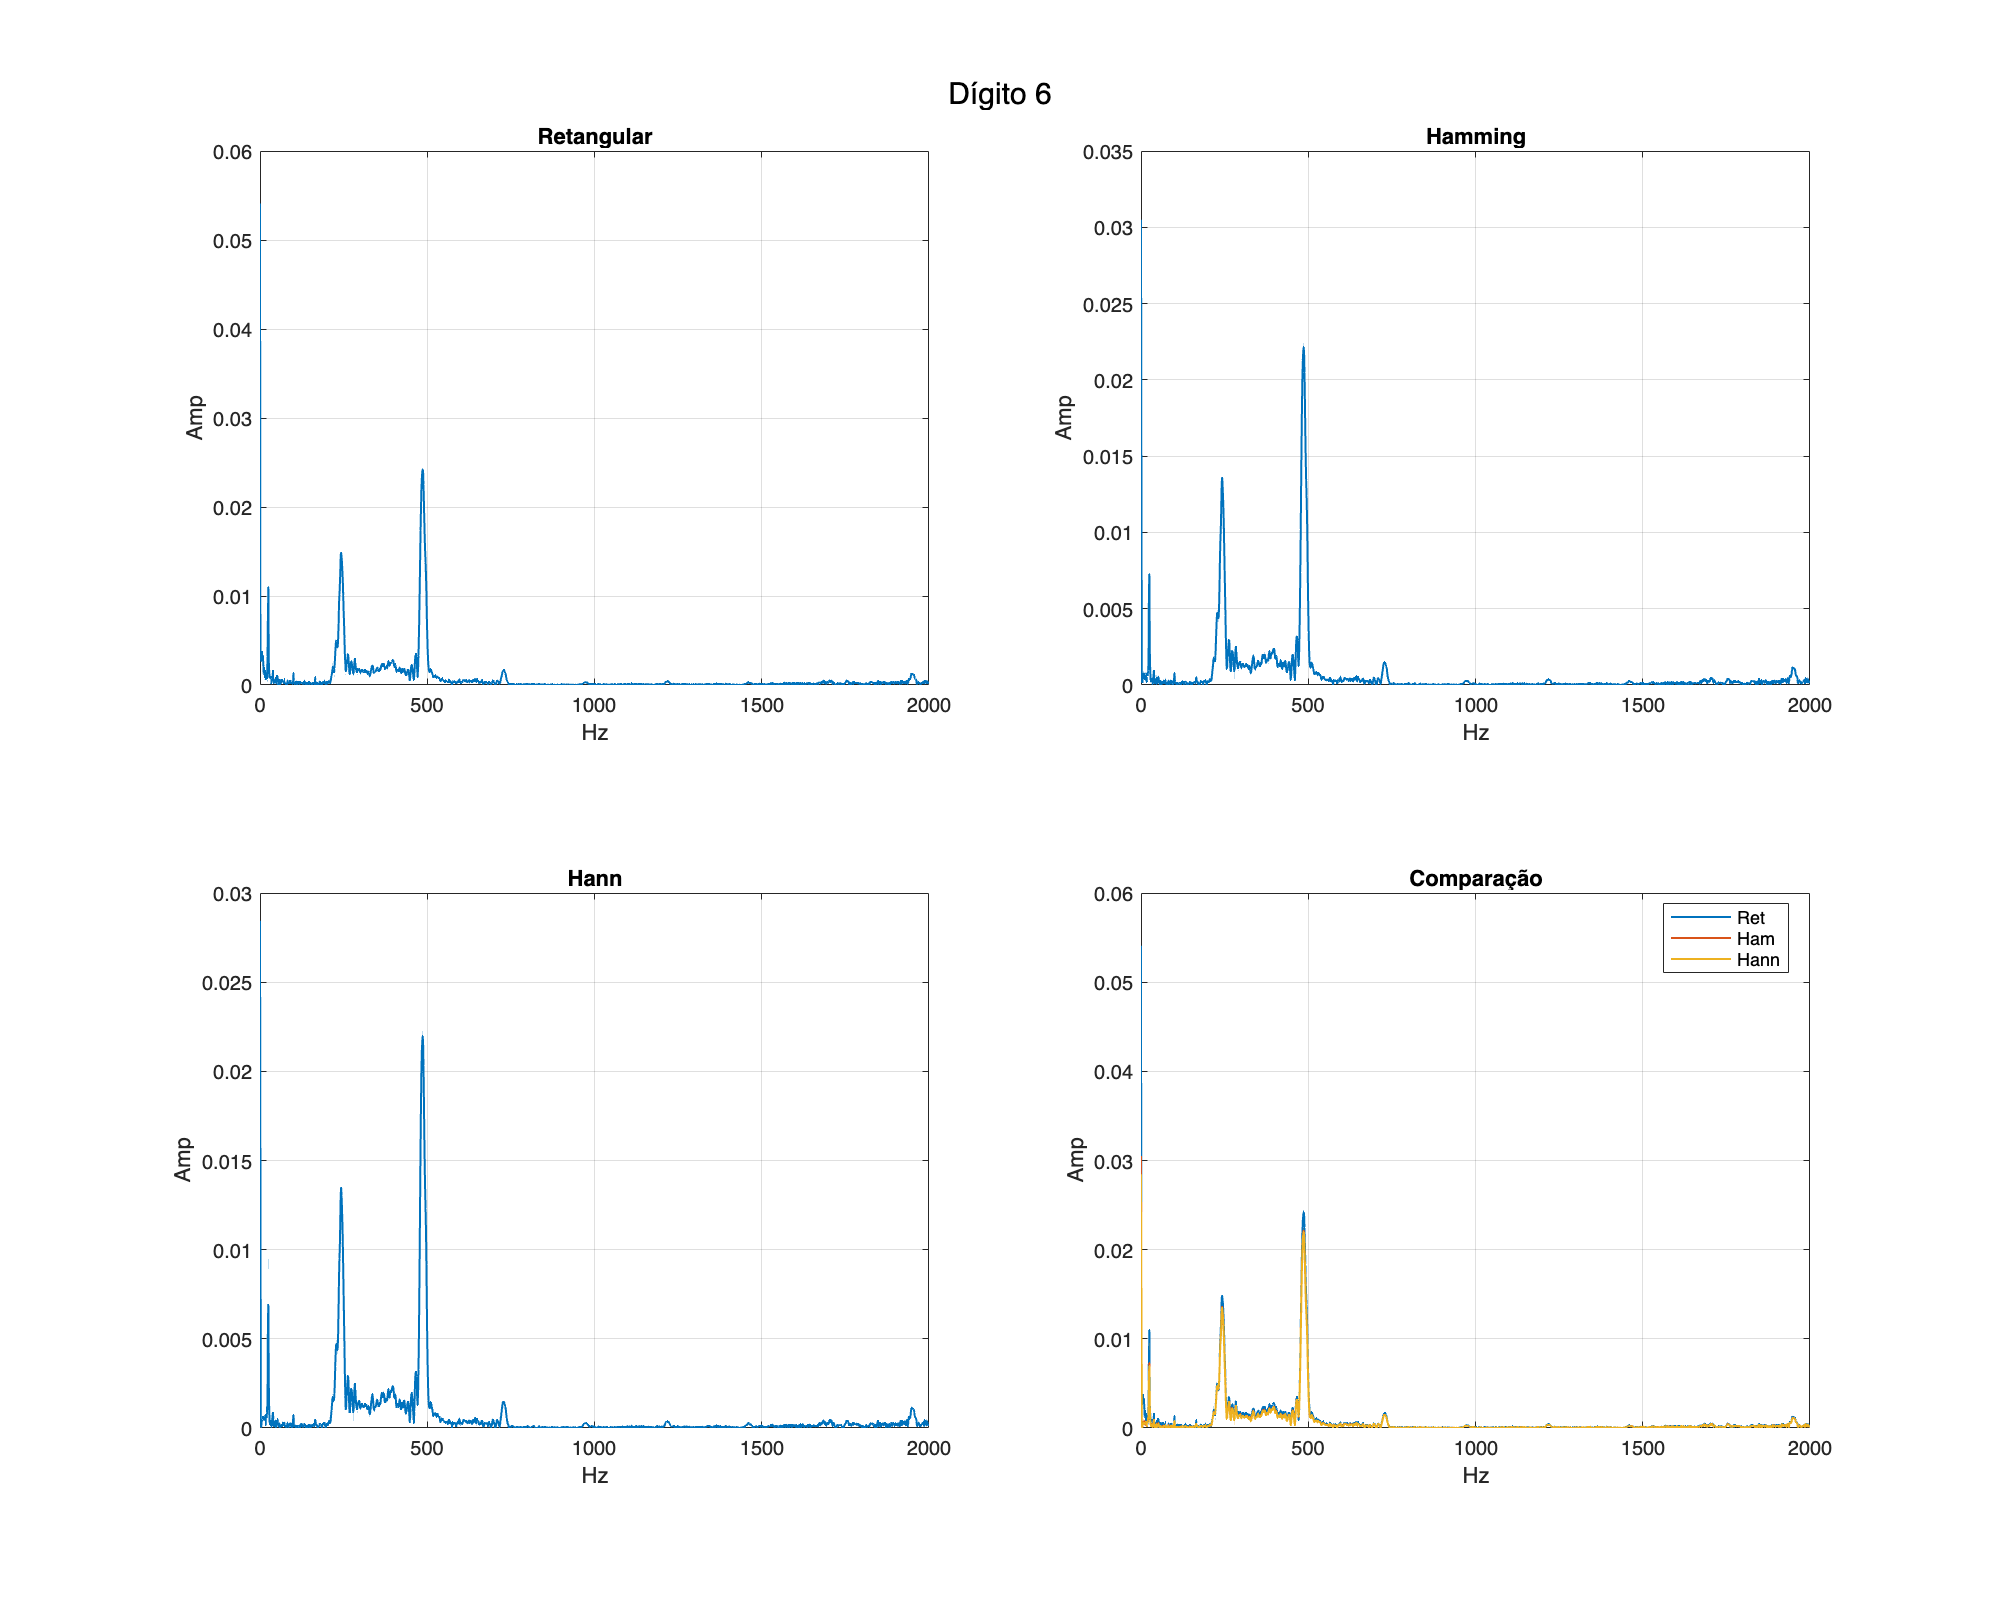

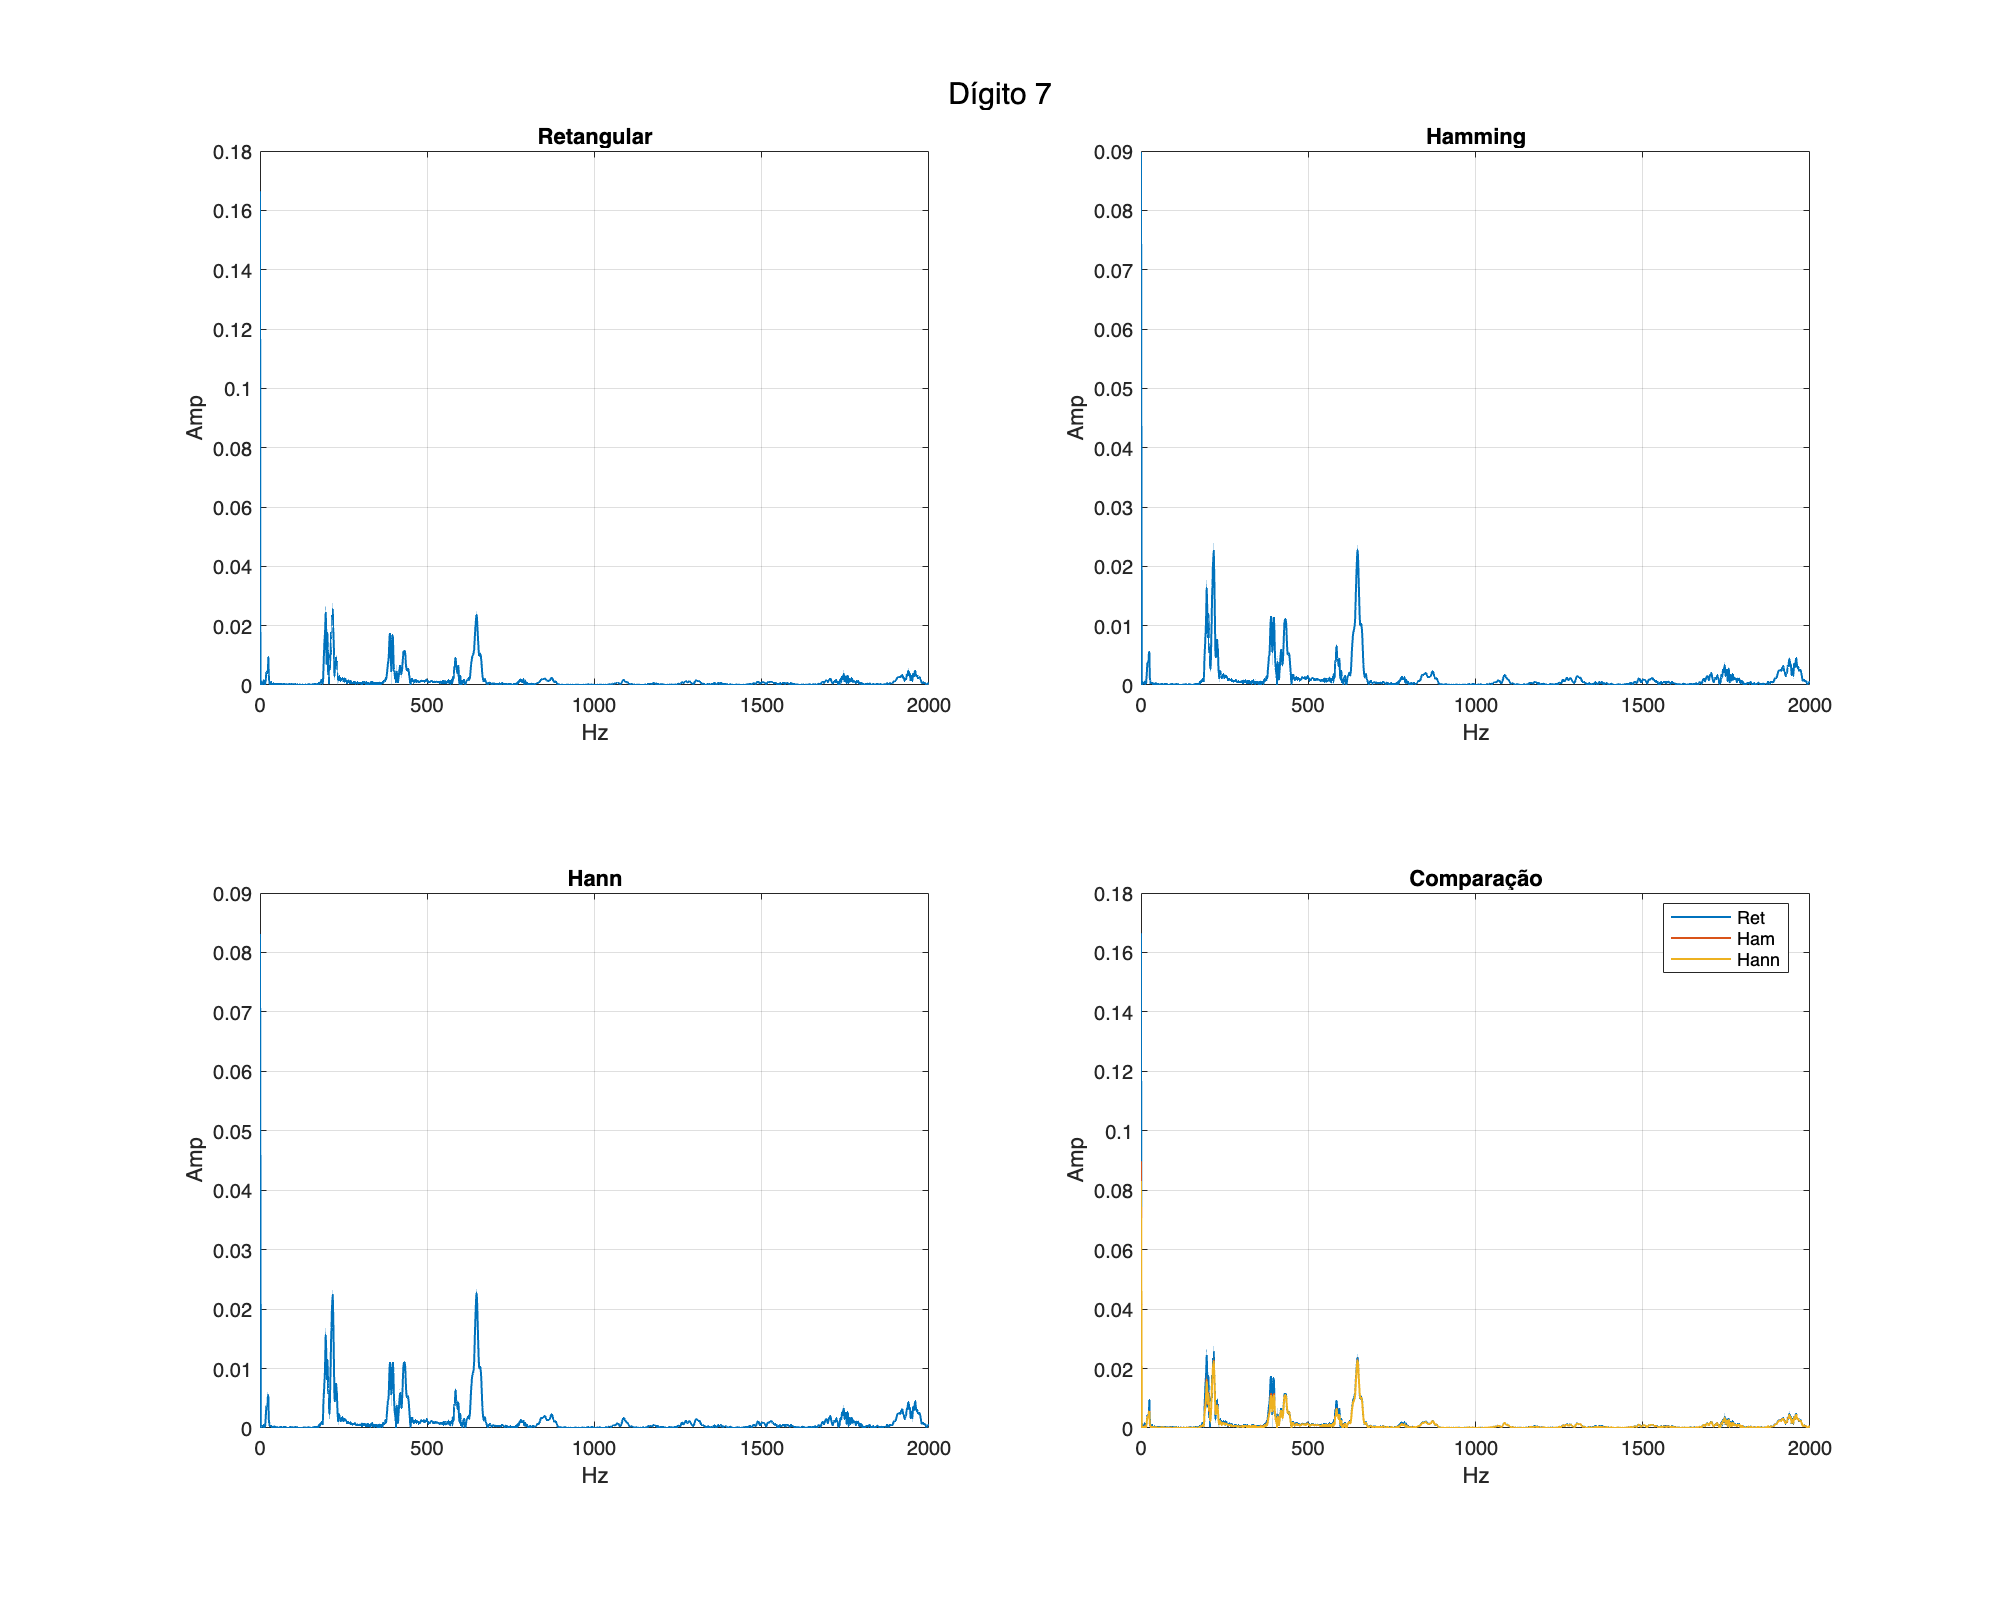


%% Aplicação de Janelas e Espectros para cada Dígito
% Para cada dígito, plota espectros em subplots 2×2
for k = 1:numel(digitos_all)
    idx = find(y==digitos_all(k),1);     % primeira ocorrência do dígito
    s = tabela.Sinal_Processado{idx};
    fs = tabela.Taxa_Amostragem(idx);
    N = length(s); t = (0:N-1)/fs;
    % Aplica janelas e computa FFT normalizada
    S_rect    = fft(s .* ones(N,1)) / N;
    S_hamming = fft(s .* hamming(N)) / N;
    S_hann    = fft(s .* hann(N))    / N;
    % Seleciona frequências até 2000 Hz
    nFreq = floor(N/2) + 1;
    freq = (0:nFreq-1) * fs / N;
    idx2000 = freq <= 2000;
    f2000 = freq(idx2000);
    ampR = abs(S_rect(1:nFreq)); ampH = abs(S_hamming(1:nFreq)); ampN = abs(S_hann(1:nFreq));
    ampR = ampR(idx2000); ampH = ampH(idx2000); ampN = ampN(idx2000);

    
    figure('Name',sprintf('Dígito %d - Espectros de Janelas', digitos_all(k)), ...
           'NumberTitle','off','Position',[100 100 1000 800]);
    sgtitle(sprintf('Dígito %d', digitos_all(k)));
    % Subplots dos espectros
    subplot(2,2,1);
    plot(f2000, ampR, 'LineWidth',1); title('Retangular'); xlabel('Hz'); ylabel('Amp'); xlim([0 2000]); grid on;
    subplot(2,2,2);
    plot(f2000, ampH, 'LineWidth',1); title('Hamming'); xlabel('Hz'); ylabel('Amp'); xlim([0 2000]); grid on;
    subplot(2,2,3);
    plot(f2000, ampN, 'LineWidth',1); title('Hann'); xlabel('Hz'); ylabel('Amp'); xlim([0 2000]); grid on;
    subplot(2,2,4);
    plot(f2000, ampR, 'LineWidth',1); hold on;
    plot(f2000, ampH, 'LineWidth',1); plot(f2000, ampN, 'LineWidth',1);
    title('Comparação'); xlabel('Hz'); ylabel('Amp'); legend('Ret','Ham','Hann','Location','best'); xlim([0 2000]); grid on;
end